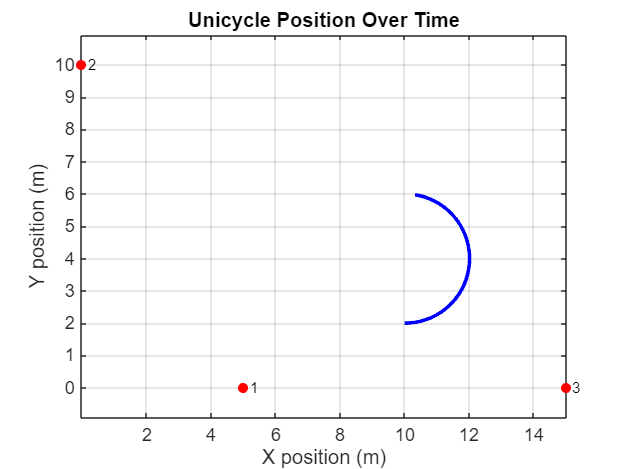


clear all
close all 

%% 1 Groundtruth Dynamical model

% Define parameters
dt = 0.1;           % Time step
T = 30;             % Total simulation time
N = T/dt;           % Number of time steps

% Initial conditions
x = 10;              % Initial x position
y = 2;              % Initial y position
theta = 0;          % Initial orientation (radians)

Anc = [5, 0, 15;
       0, 10, 0];

% Allocate memory for storing position and orientation
x_pos = zeros(1, N);
y_pos = zeros(1, N);
theta_pos = zeros(1, N);

% Define control inputs (velocity and angular velocity)
v = 0.2;            % Constant linear velocity (m/s)
w = 0.1;            % Constant angular velocity (rad/s)

% Simulation loop
for i = 1:N
    % Store the current position and orientation
    x_pos(i) = x;
    y_pos(i) = y;
    theta_pos(i) = theta;
    
    % Update the position and orientation using unicycle model equations
    x = x + v * cos(theta) * dt;
    y = y + v * sin(theta) * dt;
    theta = theta + w * dt;
end

% Plot the position of the unicycle over time
figure;
plot(x_pos, y_pos, 'b', 'LineWidth', 2); 
hold on 
plot(Anc(1,:), Anc(2,:), 'ro', 'MarkerSize', 5, 'MarkerFaceColor', 'r'); % Plot the Anc points

% Add text labels near the Anc points
for i = 1:size(Anc, 2)
    text(Anc(1,i) + 0.2, Anc(2,i), num2str(i), 'Color', 'black', 'FontSize', 8); % Adjust the position and color as needed
end
xlabel('X position (m)');
ylabel('Y position (m)');
title('Unicycle Position Over Time');
grid on;
axis equal;
hold off


% 1.2 Measures modelling

% Getting the measurements
z = zeros(3,N);
for i=1:N
    c = 299792458; 
    w = 1*1e-6; % incertezza sul sensore ------------------
  
    w1 = w * randn(1); % incertezza sull'orologio che riceve
    w2 = w * randn(1);
    w3 = w * randn(1);
    
    % om1 = c * w1^2; % sbagliata parte
    % om2 = c * w2^2;
    % om3 = c * w3^2;
    % 
    % Vettore di misurazioni pulite
    Pos = [x_pos(i);y_pos(i)];
    p1 = norm(Anc(:,1) - Pos);
    p2 = norm(Anc(:,2) - Pos);
    p3 = norm(Anc(:,3) - Pos);
    
    % Misure rumorose
    % p1b = (p1/c + w1)*c;
    % p2b = (p2/c + w2)*c;
    % p3b = (p3/c + w3)*c;
    p1b = p1 + randn*0.2;
    p2b = p2 + randn*0.2;
    p3b = p3 + randn*0.2;
    z(:,i) = [p1b;p2b;p3b];
    
end


%EKF PREDICT
Q = diag(rand(2,1)*2e-2);
R = diag([1,1,1]).*2e-2; % Measurement matrix

% Impostiamo le condizioni iniziali con una covarianza molto alta
% x0 = rand(2,1).*5
x0 = [10;4]

x0 =     10
     4


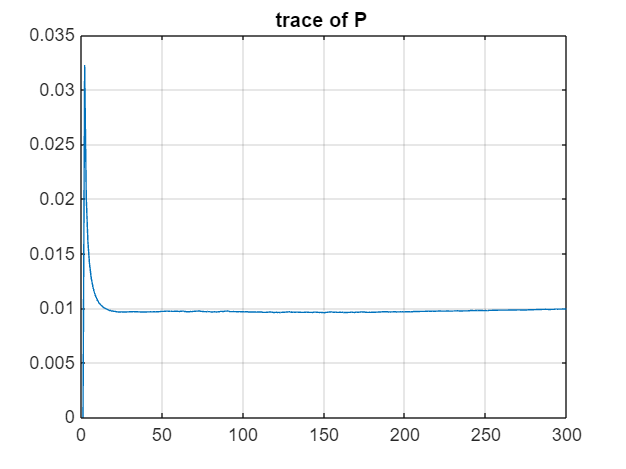

P0 = diag([3,3]); 

x  = zeros(2,N);
xp = zeros(2,N);


perf = zeros(1,N);
    
P=P0;
tht = 0;
x(:,1) = x0;

for i= 1:N-1
    
    %PREDICTION:
    xp(1,i+1) = x(1,i)+ dt*v*cos(tht);
    xp(2,i+1) = x(2,i)+ dt*v*sin(tht);
    tht = tht + dt * w;

    A = eye(2);
    Pp = A*P*A' + Q;

    %UPDATE:
    % linearization of H matrix
    d1 = sqrt((xp(1,i+1)-Anc(1,1))^2 + (xp(2,i+1)-Anc(2,1))^2);
    d2 = sqrt((xp(1,i+1)-Anc(1,2))^2 + (xp(2,i+1)-Anc(2,2))^2);
    d3 = sqrt((xp(1,i+1)-Anc(1,3))^2 + (xp(2,i+1)-Anc(2,3))^2);

    Hlin = [  (xp(1,i+1) - Anc(1,1))/d1,  (xp(2,i+1) - Anc(2,1))/d1;
              (xp(1,i+1) - Anc(1,2))/d2,  (xp(2,i+1) - Anc(2,2))/d2;
              (xp(1,i+1) - Anc(1,3))/d3,  (xp(2,i+1) - Anc(2,3))/d3];

    % compute the function h(x) 
    h_x = [d1;d2;d3];

    K = Pp*Hlin'/(Hlin*Pp*Hlin' + R);

    x(:,i+1) = xp(:,i+1) + K*(z(:,i+1)- h_x);
    
    P = (eye(2)- K*Hlin)*Pp;
    perf(i+1) = sum(diag(P));

end



figure();
plot(perf);
grid on
title('trace of P ');

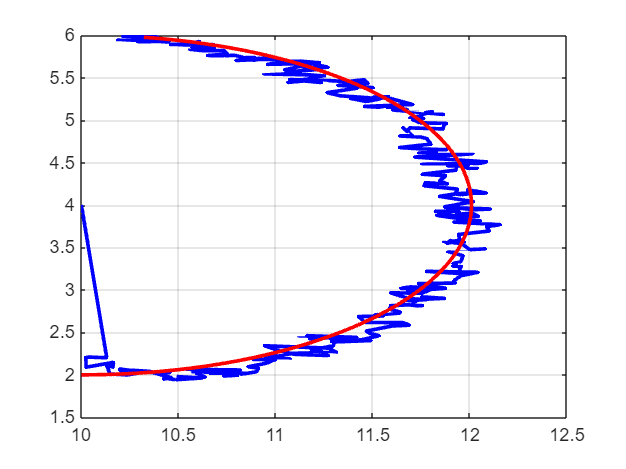



figure();
plot(x(1,:), x(2,:), 'b', 'LineWidth', 2); 
hold on 
plot(x_pos, y_pos, 'r', 'LineWidth', 2); 
grid

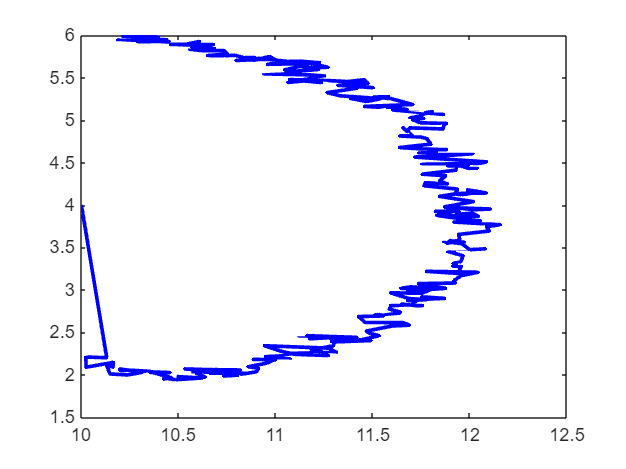

figure();
plot(x(1,:), x(2,:), 'b', 'LineWidth', 2); 